# External flow analysis

## External energy data analysis

Import interface flow data (5-min)

% interfaceFlow = importInterfaceFlow("D:\EERL\2019_NYISO\2019_Interface_Flow\20190101ExternalLimitsFlows.csv")

**list of interface**

Import/Export proxy (11);

HQ Proxy (3): HQCD (Cedars), HQEX (Import_Export), HQNY (Chateauguay),

NPX Proxy (3): NENP (1385 Northport), NPX-AC (NE-NY), NPX-CSC,

OH Proxy (1): OH-AC, 

PJM Proxy (4): PJDF (Neptune), PJM-AC (PJ-NY, Keystone), PJM-HTP (Hudsuon TP), PJM-VFT (Linden VFT)

% groupsummary(interfaceFlow, "InterfaceName")
% interfaceNames = unique(interfaceFlow.InterfaceName);
% externalIdx = startsWith(string(interfaceNames), "SCH - ");
% externalFlowNames = interfaceNames(externalIdx)
% internalFlowNames = interfaceNames(~externalIdx)

### Import hourly balancing market advisory data

energyFileDir = "D:\EERL\2019_NYISO\2019_Balancing_Market_Advisory\";
energyFileName = "2019*";
energyDataStore = fileDatastore(energyFileDir + energyFileName, "ReadFcn", @importExternalEnergy, "UniformRead", true, "FileExtensions",'.csv');
energyAll = readall(energyDataStore);

clear energyDataStore;

Error using matlab.io.datastore.FileDatastore/readall (line 42)
All tables being vertically concatenated must have the same number of variables.

### External energy data cleaning

- 03/10/2019 02:00 data is missing: linear interpolation.

- 11/03/2019 01:00 has duplicates: remove the duplicate record.

variableNames = energyAll.Properties.VariableNames(2:end);
% Clean missing data
beforeMissingTime = datetime('03/10/2019 01:00:00',"Format","MM/dd/uuuu HH:mm:ss");
afterMissingTime = datetime('03/10/2019 03:00:01',"Format","MM/dd/uuuu HH:mm:ss");
energyAllMissing = energyAll(energyAll.TimeStamp >= beforeMissingTime & energyAll.TimeStamp < afterMissingTime | ismissing(energyAll.TimeStamp),:);
energyAllAddMissing = array2table(mean(energyAllMissing{:, 2:end}, 1),"VariableNames",variableNames);
TimeStamp = datetime("03/10/2019 02:00:00","Format","MM/dd/uuuu HH:mm:ss");
energyAllAddMissing = addvars(energyAllAddMissing, TimeStamp, 'Before', variableNames(1));
energyAllAddMissing.Properties.VariableNames(2:end) = variableNames;

% Clean duplicated data
dupTime = datetime('11/03/2019 01:00:00',"Format","MM/dd/uuuu HH:mm:ss");
energyAllNoDup = energyAll(energyAll.TimeStamp ~= dupTime, :);
energyAllDup = energyAll(energyAll.TimeStamp == dupTime, :);
energyAllRemoveDup = array2table(mean(energyAllDup{:, 2:end}, 1),"VariableNames",variableNames);
TimeStamp = datetime("11/03/2019 01:00:00","Format","MM/dd/uuuu HH:mm:ss");
energyAllRemoveDup = addvars(energyAllRemoveDup, TimeStamp, 'Before', variableNames(1));
energyAllRemoveDup.Properties.VariableNames(2:end) = variableNames;
energyAllCleaned = [energyAllNoDup; energyAllAddMissing; energyAllRemoveDup];
energyAllCleaned = sortrows(energyAllCleaned, "TimeStamp")

energyAllCleaned = 8760×19 table
       TimeStamp        NetImports    DNI_HQ    DNI_NPX    DNI_OH    DNI_PJM    DNI_NYISO    DNI_DELTA    HQProxyDNIHQCD    HQProxyDNIHQEX    HQProxyDNIHQNY    NPXProxyDNINENP    NPXProxyDNINPXAC    NPXProxyDNINPXCSC    OHProxyDNIOHAC    PJMProxyDNIPJDF    PJMProxyDNIPJMAC    PJMProxyDNIPJMHTP    PJMProxyDNIPJMVFT
    ________________    __________    ______    _______    ______    _______    _________    _________    ______________    ______________    ________

#### Create net import table and proxy flow table

netImportAll = energyAllCleaned(:, ["TimeStamp","NetImports","DNI_HQ","DNI_NPX","DNI_OH","DNI_PJM","DNI_NYISO","DNI_DELTA"])

netImportAll = 8760×8 table
       TimeStamp        NetImports    DNI_HQ    DNI_NPX    DNI_OH    DNI_PJM    DNI_NYISO    DNI_DELTA
    ________________    __________    ______    _______    ______    _______    _________    _________

    01/01/2019 00:00       1875         326       -733      1150      1132        1875            0   
    01/01/2019 01:00       1526         229       -628      1150       775        1526         -349   
    01/01/2019 02:00       1187         205       -783      1150       615        1187         -339   
    01/01/2019 03:00       1104         205       -877      1150       626        1104          -83   
    01/01/2019 04:00       1003         205      -1000      1150       648       

netProxyFlowAll = energyAllCleaned(:, [1,2,9:end])

netProxyFlowAll = 8760×13 table
       TimeStamp        NetImports    HQProxyDNIHQCD    HQProxyDNIHQEX    HQProxyDNIHQNY    NPXProxyDNINENP    NPXProxyDNINPXAC    NPXProxyDNINPXCSC    OHProxyDNIOHAC    PJMProxyDNIPJDF    PJMProxyDNIPJMAC    PJMProxyDNIPJMHTP    PJMProxyDNIPJMVFT
    ________________    __________    ______________    ______________    ______________    _______________    ________________    _________________    ______________    _______________    ________________    _________________    _________________

    01/01/2019 00:00       18

#### Plot hourly net imports in 2019

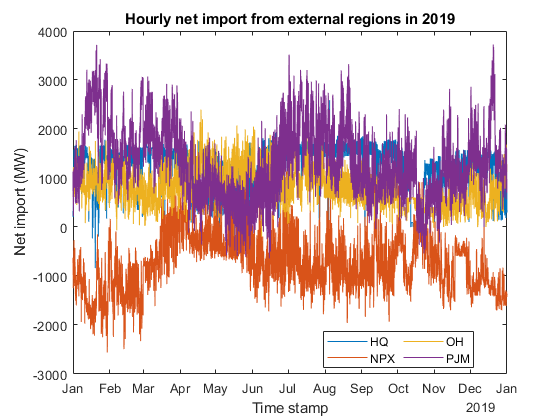

figure;
plot(netImportAll.TimeStamp, netImportAll.DNI_HQ);
hold on;
plot(netImportAll.TimeStamp, netImportAll.DNI_NPX);
plot(netImportAll.TimeStamp, netImportAll.DNI_OH);
plot(netImportAll.TimeStamp, netImportAll.DNI_PJM);
hold off;
legend(["HQ","NPX","OH","PJM"],"Location","best",'NumColumns',2);
xlabel("Time stamp");
ylabel("Net import (MW)");
title("Hourly net import from external regions in 2019");

### Net import daily and monthly summary

netImportDailySum = groupsummary(netImportAll,"TimeStamp","day","sum",["NetImports","DNI_HQ","DNI_NPX","DNI_OH","DNI_PJM","DNI_NYISO","DNI_DELTA"]);
netImportDailySum.day_TimeStamp = datetime(string(netImportDailySum.day_TimeStamp),"InputFormat","dd-MMM-uuuu","Format","MM/dd/uuuu");
netImportDailySum = removevars(netImportDailySum, "GroupCount");
netImportMonthlySum = groupsummary(netImportAll,"TimeStamp","month","sum",["NetImports","DNI_HQ","DNI_NPX","DNI_OH","DNI_PJM","DNI_NYISO","DNI_DELTA"]);
netImportMonthlySum.month_TimeStamp = datetime(string(netImportMonthlySum.month_TimeStamp),"InputFormat","MMM-uuuu","Format","MM/uuuu");
netImportMonthlySum = removevars(netImportMonthlySum, "GroupCount");

#### Plot monthly net import

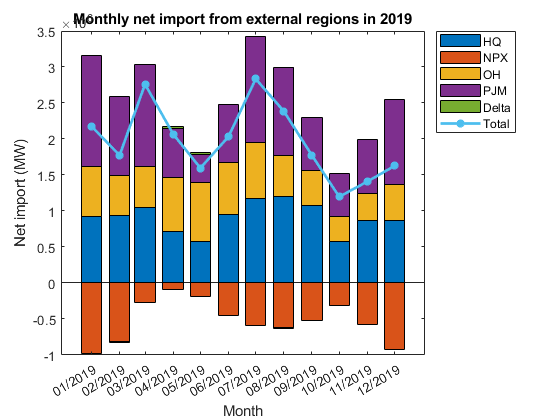

figure;
y = table2array(netImportMonthlySum(:, ["sum_DNI_HQ","sum_DNI_NPX","sum_DNI_OH","sum_DNI_PJM","sum_DNI_DELTA"]));
bar(netImportMonthlySum.month_TimeStamp, y, 'stacked');
hold on;
plot(netImportMonthlySum.month_TimeStamp, netImportMonthlySum.sum_NetImports,"*-","LineWidth",2);
hold off;
legend(["HQ","NPX","OH","PJM","Delta","Total"],"Location","bestoutside");
xlabel("Month");
ylabel("Net import (MW)");
title("Monthly net import from external regions in 2019");

#### Plot daily net import in Jan

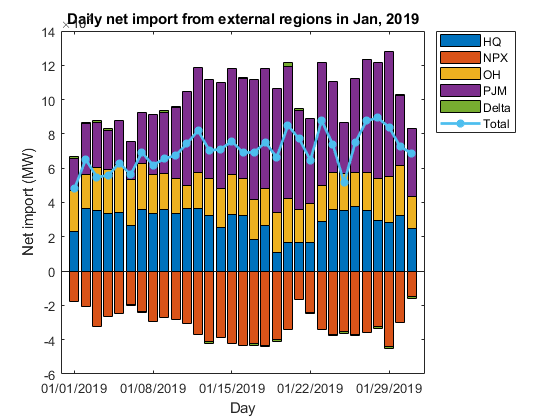

figure;
netImportDailySumJan = netImportDailySum(netImportDailySum.day_TimeStamp.Month == 1, :);
y = table2array(netImportDailySumJan(:, ["sum_DNI_HQ","sum_DNI_NPX","sum_DNI_OH","sum_DNI_PJM","sum_DNI_DELTA"]));
bar(netImportDailySumJan.day_TimeStamp, y, 'stacked');
hold on;
plot(netImportDailySumJan.day_TimeStamp, netImportDailySumJan.sum_NetImports,"*-","LineWidth",2);
hold off;
legend(["HQ","NPX","OH","PJM","Delta","Total"],"Location","bestoutside");
xlabel("Day");
ylabel("Net import (MW)");
title("Daily net import from external regions in Jan, 2019");

### Proxy flow data analysis

proxyNames = string(netProxyFlowAll.Properties.VariableNames(3:end));
proxyNames = extractAfter(proxyNames, 'DNI');
netProxyFlowAll.Properties.VariableNames(3:end) = proxyNames;

netProxyFlowAll = 8760×13 table
       TimeStamp        NetImports    HQCD    HQEX    HQNY    NENP    NPXAC    NPXCSC    OHAC    PJDF    PJMAC    PJMHTP    PJMVFT
    ________________    __________    ____    ____    ____    ____    _____    ______    ____    ____    _____    ______    ______

    01/01/2019 00:00       1875         0     150     176     139      -872      0       1150    660     -128      285       315  
    01/01/2019 01:00       1526         0     150      79     111      -739      0       1150    660     -330      130       315  
 

netProxyFlowMissing1 = netProxyFlowAll(ismissing(netProxyFlowAll.PJMAC), :)

netProxyFlowMissing1 = 984×13 table
       TimeStamp        NetImports    HQCD    HQEX    HQNY    NENP    NPXAC    NPXCSC    OHAC    PJDF    PJMAC    PJMHTP    PJMVFT
    ________________    __________    ____    ____    ____    ____    _____    ______    ____    ____    _____    ______    ______

    02/06/2019 00:00       3026       1125      0     -123      0      600      660      368     126      NaN      NaN       NaN  
    02/06/2019 01:00       2756       1125     48     -153      0      600      495      371       0      NaN      NaN       NaN

datetime(unique(string(datetime(netProxyFlowMissing1.TimeStamp,"Format","MM/dd/uuuu"))),"InputFormat","MM/dd/uuuu","Format","MM/dd/uuuu")

ans = 41×1 datetime array
   02/06/2019
   04/03/2019
   04/09/2019
   04/10/2019
   04/11/2019
   04/21/2019
   05/01/2019
   05/02/2019
   05/04/2019
   05/05/2019
   05/06/2019
   05/07/2019
   05/08/2019
   05/09/2019
   05/10/2019
   05/11/2019
   05/12/2019
   05/13/2019
   05/16/2019
   05/19/2019
   05/22/2019
   05/27/2019
   05/28/2019
   05/29/2019
   08/27/2019
   09/08/2019
   10/15/2019
   10/16/2019
   10/17/2019
   10/18/2019


netProxyFlowMissing2 = netProxyFlowAll(ismissing(netProxyFlowAll.NPXCSC), :)

netProxyFlowMissing2 = 72×13 table
       TimeStamp        NetImports    HQCD    HQEX    HQNY    NENP    NPXAC    NPXCSC    OHAC    PJDF    PJMAC    PJMHTP    PJMVFT
    ________________    __________    ____    ____    ____    ____    _____    ______    ____    ____    _____    ______    ______

    05/07/2019 00:00       1224       -600    850     660     -123      62      NaN      NaN     NaN      NaN      NaN       NaN  
    05/07/2019 01:00       1275       -600    950     495     -117     222      NaN      NaN     NaN      NaN      NaN       NaN 

% testTable = readtable("D:\EERL\2019_NYISO\2019_Balancing_Market_Advisory\20190101HAM_energy_rep.csv")
testTable1 = importExternalEnergy("D:\EERL\2019_NYISO\2019_Balancing_Market_Advisory\20190101HAM_energy_rep.csv")

testTable1 = 24×19 table
       TimeStamp        NetImports    DNI_HQ    DNI_NPX    DNI_OH    DNI_PJM    DNI_NYISO    DNI_DELTA    HQProxyDNIHQCD    HQProxyDNIHQEX    HQProxyDNIHQNY    NPXProxyDNINENP    NPXProxyDNINPXAC    NPXProxyDNINPXCSC    OHProxyDNIOHAC    PJMProxyDNIPJDF    PJMProxyDNIPJMAC    PJMProxyDNIPJMHTP    PJMProxyDNIPJMVFT
    ________________    __________    ______    _______    ______    _______    _________    _________    ______________    ______________    ______________</

testTable2 = importExternalEnergy("D:\EERL\2019_NYISO\2019_Balancing_Market_Advisory\20190403HAM_energy_rep.csv")

testTable2 = 24×19 table
       TimeStamp        NetImports    DNI_HQ    DNI_NPX    DNI_OH    DNI_PJM    DNI_NYISO    DNI_DELTA    HQProxyDNIHQCD    HQProxyDNIHQEX    HQProxyDNIHQNY    NPXProxyDNINENP    NPXProxyDNINPXAC    NPXProxyDNINPXCSC    OHProxyDNIOHAC    PJMProxyDNIPJDF    PJMProxyDNIPJMAC    PJMProxyDNIPJMHTP    PJMProxyDNIPJMVFT
    ________________    __________    ______    _______    ______    _______    _________    _________    ______________    ______________    ______________</

testTable3 = importExternalEnergy("D:\EERL\2019_NYISO\2019_Balancing_Market_Advisory\20190507HAM_energy_rep.csv")

testTable3 = 24×19 table
       TimeStamp        NetImports    DNI_HQ    DNI_NPX    DNI_OH    DNI_PJM    DNI_NYISO    DNI_DELTA    HQProxyDNIHQCD    HQProxyDNIHQEX    HQProxyDNIHQNY    NPXProxyDNINENP    NPXProxyDNINPXAC    NPXProxyDNINPXCSC    OHProxyDNIOHAC    PJMProxyDNIPJDF    PJMProxyDNIPJMAC    PJMProxyDNIPJMHTP    PJMProxyDNIPJMVFT
    ________________    __________    ______    _______    ______    _______    _________    _________    ______________    ______________    ______________</

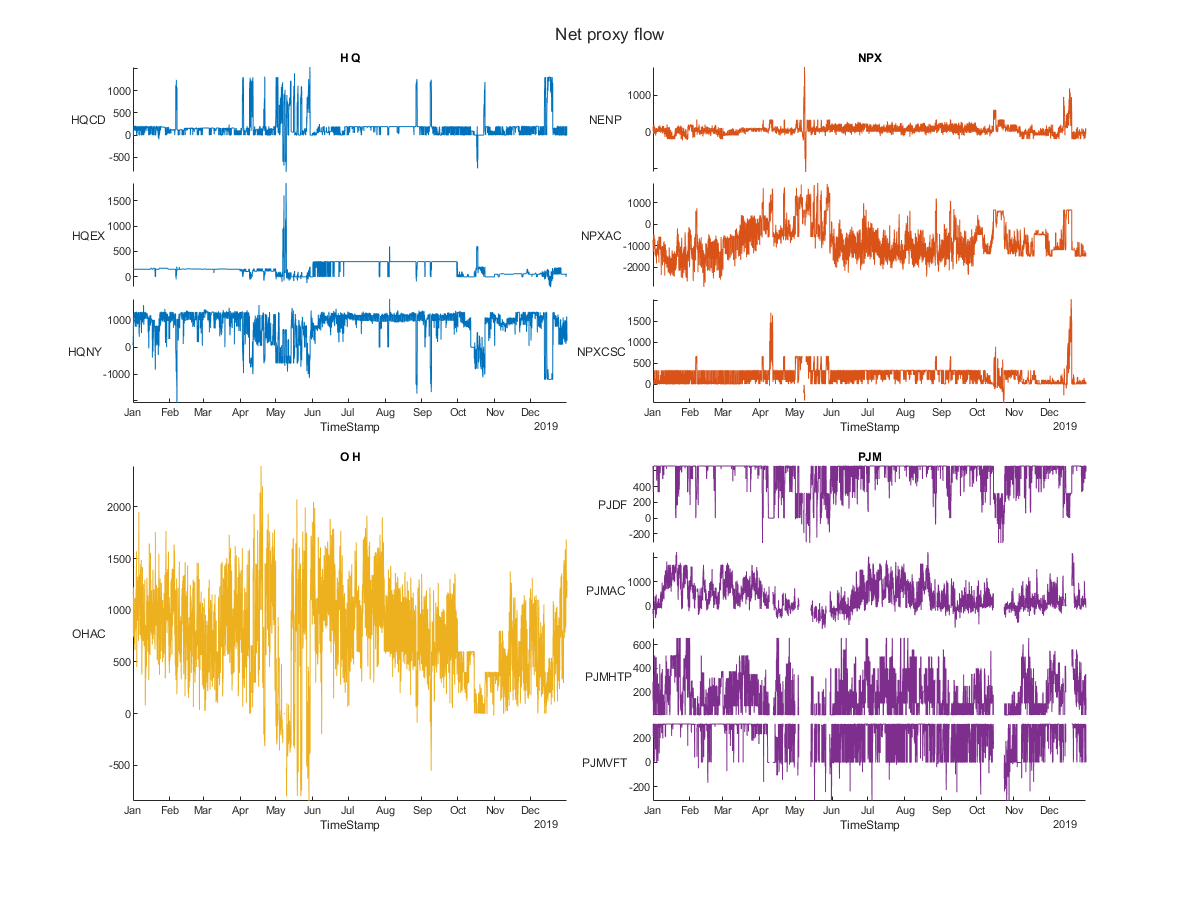

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
nexttile;
stackedplot(netProxyFlowAll,["HQCD","HQEX","HQNY"],"XVariable","TimeStamp")
title("H Q");
nexttile;
stackedplot(netProxyFlowAll,["NENP","NPXAC","NPXCSC"],"XVariable","TimeStamp","Color",'#D95319')
title("NPX");

nexttile;
stackedplot(netProxyFlowAll,["OHAC"],"XVariable","TimeStamp","Color",'#EDB120')
title("O H");

nexttile;
stackedplot(netProxyFlowAll,["PJDF","PJMAC","PJMHTP","PJMVFT"],"XVariable","TimeStamp","Color",'#7E2F8E')
title("PJM");

title(t, "Net proxy flow");
set(gcf, "Position", [100, 100, 1200, 900]);

## Price data analysis

### Import DAM zonal price data

% priceFileDir = "D:\EERL\2019_NYISO\2019_DAM_LBMP_Zonal\";
% priceFileName = "2019*";
% energyDataStore = fileDatastore(priceFileDir + priceFileName, "ReadFcn", @importZonalPrice, "UniformRead", true);
% priceAll = readall(energyDataStore);
% clear priceDataStore;
% priceAll

#### Import RTM hourly integrated zonal price data

priceFileDir = "D:\EERL\2019_NYISO\2019_RTM_Integrated_LBMP_Zonal\";
priceFileName = "2019*";
priceDataStore = fileDatastore(priceFileDir + priceFileName, "ReadFcn", @importZonalPrice, "UniformRead", true,"FileExtensions",'.csv');
priceAll = readall(priceDataStore);
clear priceDataStore;

#### Import RTM hourly integrated reference bus price data

priceRefFileDir = "D:\EERL\2019_NYISO\2019_RTM_Integrated_LBMP_Reference_Bus\";
priceRefFileName = "2019*";
priceRefDataStore = fileDatastore(priceRefFileDir + priceRefFileName, "ReadFcn", @importRefPrice, "UniformRead", true,"FileExtensions",'.csv');
priceRefAll = readall(priceRefDataStore);
clear priceRefDataStore;

priceAllWRef = [priceAll; priceRefAll]

priceAllWRef = 140160×6 table
       TimeStamp        ZoneName    PTID     LBMP     MarginalCostLosses    MarginalCostCongestion
    ________________    ________    _____    _____    __________________    ______________________

    01/01/2019 00:00     CAPITL     61757     39.9           0.12                   -37.98        
    01/01/2019 00:00     CENTRL     61754     6.73           0.01                    -4.92        
    01/01/2019 00:00     DUNWOD     61760    30.23           0.15                   -28.29        
    01/01/2019 00:00     GENESE     61753     5.25          -0.07                    -3.52        
    01/01/2019 00:00     H Q        61844     1.99          -0.04                    -0.24        
    01/01/2019 00:00     HUD VL     61758    30.26           0.14       

#### Price data cleaning

- 03/10/2019 02:00 data is missing: linear interpolation.

- 11/03/2019 01:00 has duplicates: remove the duplicate record.

% Clean missing data
beforeMissingTime = datetime('03/10/2019 01:00:00',"Format","MM/dd/uuuu HH:mm:ss");
afterMissingTime = datetime('03/10/2019 03:00:01',"Format","MM/dd/uuuu HH:mm:ss");
priceAllMissing = priceAllWRef(priceAllWRef.TimeStamp >= beforeMissingTime & priceAllWRef.TimeStamp < afterMissingTime | ismissing(priceAllWRef.TimeStamp),:);
priceAllAddMissing = groupsummary(priceAllMissing, ["ZoneName","PTID"],"mean",["LBMP","MarginalCostLosses","MarginalCostCongestion"]);
TimeStamp = datetime(repelem("03/10/2019 02:00:00", 16)',"Format","MM/dd/uuuu HH:mm:ss");
priceAllAddMissing = addvars(priceAllAddMissing, TimeStamp, 'Before', 'ZoneName');
priceAllAddMissing = removevars(priceAllAddMissing, "GroupCount");
priceAllAddMissing.Properties.VariableNames = ["TimeStamp","ZoneName","PTID","LBMP","MarginalCostLosses","MarginalCostCongestion"];

% Clean duplicated data
dupTime = datetime('11/03/2019 01:00:00',"Format","MM/dd/uuuu HH:mm:ss");
priceAllNoDup = priceAllWRef(priceAllWRef.TimeStamp ~= dupTime, :);
priceAllDup = priceAllWRef(priceAllWRef.TimeStamp == dupTime, :);
priceAllRemoveDup = groupsummary(priceAllDup, ["ZoneName","PTID"],"mean",["LBMP","MarginalCostLosses","MarginalCostCongestion"]);
TimeStamp = datetime(repelem("11/03/2019 01:00:00", 16)',"Format","MM/dd/uuuu HH:mm:ss");
priceAllRemoveDup = addvars(priceAllRemoveDup, TimeStamp, 'Before', 'ZoneName');
priceAllRemoveDup = removevars(priceAllRemoveDup, "GroupCount");
priceAllRemoveDup.Properties.VariableNames = ["TimeStamp","ZoneName","PTID","LBMP","MarginalCostLosses","MarginalCostCongestion"];
priceAllCleaned = [priceAllNoDup; priceAllAddMissing; priceAllRemoveDup];
priceAllCleaned = sortrows(priceAllCleaned, "TimeStamp");

#### Get a subset of external region price

externalZones = categorical(["H Q","NPX","O H","PJM"]);
priceExternal = priceAllCleaned(ismember(priceAllCleaned.ZoneName, externalZones), :);
priceHQ = priceExternal(priceExternal.ZoneName == "H Q", :);
priceNPX = priceExternal(priceExternal.ZoneName == "NPX", :);
priceOH = priceExternal(priceExternal.ZoneName == "O H", :);
pricePJM = priceExternal(priceExternal.ZoneName == "PJM", :);
priceRef = priceAllCleaned(priceAllCleaned.ZoneName == "NYISO_LBMP_REFERENCE", :);

priceHQ.Diff = priceHQ.LBMP - priceRef.LBMP;
priceNPX.Diff = priceNPX.LBMP - priceRef.LBMP;
priceOH.Diff = priceOH.LBMP - priceRef.LBMP;
pricePJM.Diff = pricePJM.LBMP - priceRef.LBMP;

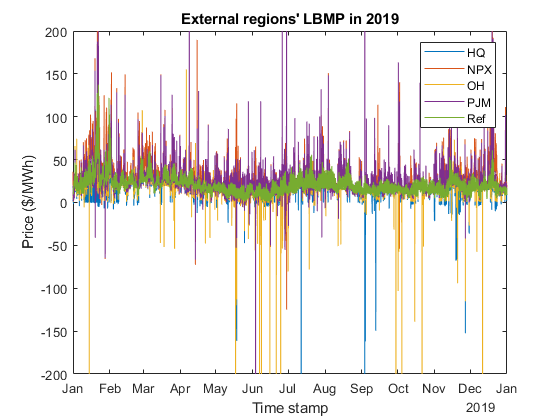

figure;
plot(priceHQ.TimeStamp, priceHQ.LBMP);
hold on;
plot(priceNPX.TimeStamp, priceNPX.LBMP);
plot(priceOH.TimeStamp, priceOH.LBMP);
plot(pricePJM.TimeStamp, pricePJM.LBMP);
plot(priceRef.TimeStamp, priceRef.LBMP);
hold off;
ylabel("Price ($/MWh)");
xlabel("Time stamp");
title("External regions' LBMP in 2019");
legend(["HQ","NPX","OH","PJM","Ref"]);

ylim([-200, 200])

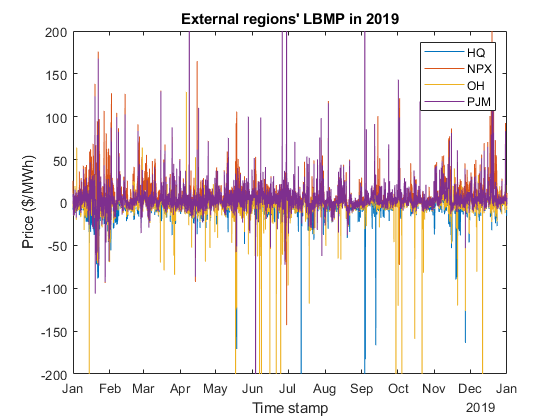

figure;
plot(priceHQ.TimeStamp, priceHQ.Diff);
hold on;
plot(priceNPX.TimeStamp, priceNPX.Diff);
plot(priceOH.TimeStamp, priceOH.Diff);
plot(pricePJM.TimeStamp, pricePJM.Diff);
% plot(priceRef.TimeStamp, priceRef.Diff);
hold off;
ylabel("Price ($/MWh)");
xlabel("Time stamp");
title("External regions' LBMP in 2019");
legend(["HQ","NPX","OH","PJM"]);

ylim([-200, 200])

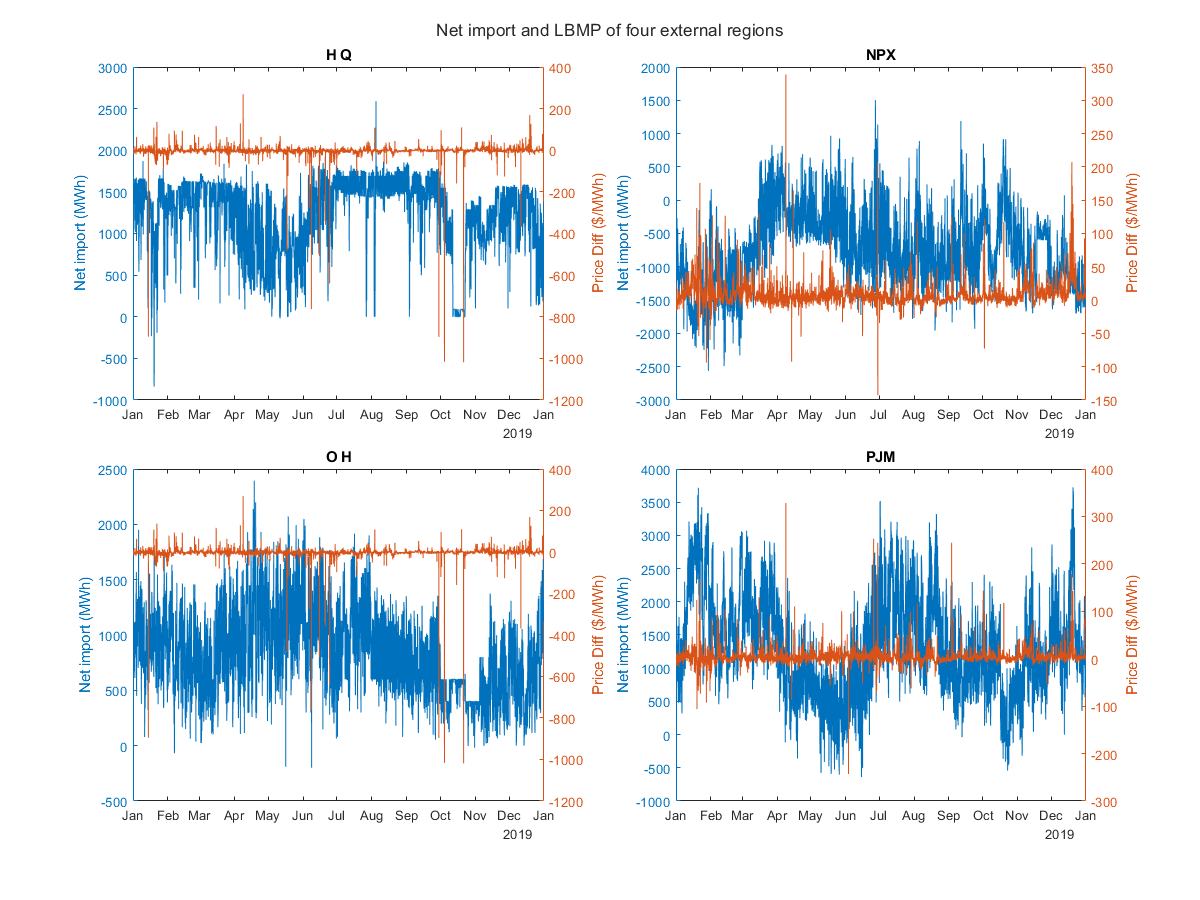

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
nexttile;
yyaxis left;
plot(netImportAll.TimeStamp, netImportAll.DNI_HQ);
ylabel("Net import (MWh)");
yyaxis right;
plot(priceHQ.TimeStamp, priceOH.Diff);
ylabel("Price Diff ($/MWh)");
title("H Q");

nexttile;
yyaxis left;
plot(netImportAll.TimeStamp, netImportAll.DNI_NPX);
ylabel("Net import (MWh)");
yyaxis right;
plot(priceNPX.TimeStamp, priceNPX.Diff);
ylabel("Price Diff ($/MWh)");
title("NPX");

nexttile;
yyaxis left;
plot(netImportAll.TimeStamp, netImportAll.DNI_OH);
ylabel("Net import (MWh)");
yyaxis right;
plot(priceOH.TimeStamp, priceOH.Diff);
ylabel("Price Diff ($/MWh)");
title("O H");

nexttile;
yyaxis left;
plot(netImportAll.TimeStamp, netImportAll.DNI_PJM);
ylabel("Net import (MWh)");
yyaxis right;
plot(pricePJM.TimeStamp, pricePJM.Diff);
ylabel("Price Diff ($/MWh)");
title("PJM");

title(t, "Net import and LBMP of four external regions");

set(gcf, "Position", [100, 100, 1200, 900]);

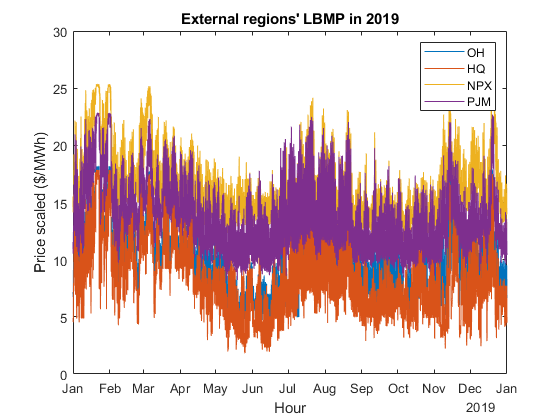

priceOH.Zscore = zscore(priceOH.LBMP);
priceOH.priceScaled = exp(priceOH.Zscore)./(1+exp(priceOH.Zscore)) * (median(priceOH.LBMP) - min(priceOH.LBMP)) + min(priceOH.LBMP);
priceHQ.Zscore = zscore(priceHQ.LBMP);
priceHQ.priceScaled = exp(priceHQ.Zscore)./(1+exp(priceHQ.Zscore)) * (median(priceHQ.LBMP) - min(priceHQ.LBMP)) + min(priceHQ.LBMP);
priceNPX.Zscore = zscore(priceNPX.LBMP);
priceNPX.priceScaled = exp(priceNPX.Zscore)./(1+exp(priceNPX.Zscore)) * (median(priceNPX.LBMP) - min(priceNPX.LBMP)) + min(priceNPX.LBMP);
pricePJM.Zscore = zscore(pricePJM.LBMP);
pricePJM.priceScaled = exp(pricePJM.Zscore)./(1+exp(pricePJM.Zscore)) * (median(pricePJM.LBMP) - min(pricePJM.LBMP)) + min(pricePJM.LBMP);
figure;
plot(priceOH.TimeStamp, priceOH.priceScaled);
hold on;
plot(priceHQ.TimeStamp, priceHQ.priceScaled);
plot(priceNPX.TimeStamp, priceNPX.priceScaled);
plot(pricePJM.TimeStamp, pricePJM.priceScaled);
hold off;
ylabel("Price scaled ($/MWh)");
xlabel("Hour");
title("External regions' LBMP in 2019");

legend(["OH","HQ","NPX","PJM"]);